
syms alpha1(t) alpha2(t) alpha3(t) alpha4(t) alpha5(t) alpha6(t) alpha7(t) T A
syms w1(t) w2(t) w3(t) w4(t) w5(t) w6(t) w7(t) 
syms beta1(t) beta2(t) beta3(t) beta4(t) beta5(t) beta6(t) beta7(t)
assume(T>0)
assume(A>0)
anguloInicialB=-15*pi/180;
anguloFinalB=15*pi/180;
A=10; %rad s^-2

alpha1(t)=10*A/T*t;
alpha2(t)=A;
alpha3(t)=-10*A/T*t;
Calpha3=A-alpha3(4*T/10);
alpha3(t)=alpha3(t)+Calpha3;
alpha4(t)=-A;
alpha5(t)=10*A/T*t;
Calpha5=alpha4(9*T/10)-alpha5(9*T/10);
alpha5(t)=alpha5(t)+Calpha5;
fprintf('Función de aceleración angular:')

Función de aceleración angular:

alpha(t)=piecewise((0<=t<T/10),alpha1,(T/10<=t<4*T/10),alpha2,(4*T/10<=t<6*T/10),alpha3,(6*T/10<=t<9*T/10),alpha4,(9*T/10<=t<=T),alpha5)

$$alpha(t) = \left\{ \begin{array}{cl} \frac{100\,t}{T} & \text{ if }10\,t<T\wedge 0\leq t\\ 10 & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ 50-\frac{100\,t}{T} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -10 & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{100\,t}{T}-100 & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

w1(t)=int(alpha1);

w2(t)=int(alpha2);
Cw2=w1(T/10)-w2(T/10);
w2(t)=w2(t)+Cw2;

w3(t)=int(alpha3);
Cw3=w2(4*T/10)-w3(4*T/10);
w3(t)=w3(t)+Cw3;

w4(t)=int(alpha4);
Cw4=w3(6*T/10)-w4(6*T/10);
w4(t)=w4(t)+Cw4;

w5(t)=int(alpha5);
Cw5=w4(9*T/10)-w5(9*T/10);
w5(t)=w5(t)+Cw5;
fprintf('Función de velocidad angular:')

Función de velocidad angular:

w(t)=piecewise((0<=t<T/10),w1,(T/10<=t<4*T/10),w2,(4*T/10<=t<6*T/10),w3,(6*T/10<=t<9*T/10),w4,(9*T/10<=t<=T),w5)

$$w(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ 10\,t-\frac{T}{2} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ 50\,t-\frac{17\,T}{2}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{19\,T}{2}-10\,t & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ 50\,T-100\,t+\sigma_{1} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{50\,t^{2}}{T} \end{array}$$


beta1(t)=int(w1)+anguloInicialB;

beta2(t)=int(w2);
Cbeta2=beta1(T/10)-beta2(T/10);
beta2(t)=beta2(t)+Cbeta2;

beta3(t)=int(w3);
Cbeta3=beta2(4*T/10)-beta3(4*T/10);
beta3(t)=beta3(t)+Cbeta3;

beta4(t)=int(w4);
Cbeta4=beta3(6*T/10)-beta4(6*T/10);
beta4(t)=beta4(t)+Cbeta4;

beta5(t)=int(w5);
Cbeta5=beta4(9*T/10)-beta5(9*T/10);
beta5(t)=beta5(t)+Cbeta5;

fprintf('Función de desplazamiento angular:')

Función de desplazamiento angular:

Fbeta(t)=piecewise((0<=t<T/10),beta1,(T/10<=t<4*T/10),beta2,(4*T/10<=t<6*T/10),beta3,(6*T/10<=t<9*T/10),beta4,(9*T/10<=t<=T),beta5)

$$Fbeta(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1}-\frac{\pi }{12} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{T^{2}}{60}-\frac{t\,\left(T-10\,t\right)}{2}-\frac{\pi }{12} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{13\,T^{2}}{12}-\frac{17\,T\,t}{2}-\frac{\pi }{12}+25\,t^{2}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{t\,\left(19\,T-10\,t\right)}{2}-\frac{151\,T^{2}}{60}-\frac{\pi }{12} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ 50\,T\,t-\frac{\pi }{12}-\frac{44\,T^{2}}{3}-50\,t^{2}+\sigma_{1} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{50\,t^{3}}{3\,T} \end{array}$$

f=0==Fbeta(T/2);

tMax_b=solve(f,T);

$$tMax\_b = \frac{\sqrt{3}\,\sqrt{\pi }}{6}$$

fprintf('Tiempo de ciclo %.3f s',tMax_b)
alpha=subs(alpha,T,tMax_b);
w=subs(w,T,tMax_b);
Fbeta=subs(Fbeta,T,tMax_b);

## Gráficas

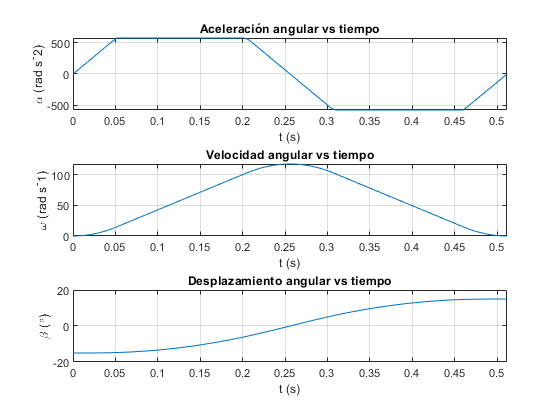

ts=linspace(0,tMax_b,100);
figure()
subplot(3,1,1)
plot(ts,alpha(ts).*180./pi)
title('Aceleración angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\alpha (rad s^-2)')
xlim([0 double(tMax_b)])

subplot(3,1,2)

plot(ts,w(ts).*180./pi)
title('Velocidad angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\omega (rad s^-1)')
xlim([0 double(tMax_b)])

subplot(3,1,3)

plot(ts,Fbeta(ts).*180./pi)
title('Desplazamiento angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\beta (\circ)')
xlim([0 double(tMax_b)])


clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada